# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

% clear all; close all;
code_eyes;

## Loading all the data

% SrcPath = '/home/peter/Projects/EEG/NN-classification/data/eyes';
% SrcNamePattern={'*_EC.mat','*_EO.mat'};
% ClassNames=categorical({'EC','EO'});
%
% channelList = {'Fp1';'AF7';'AF3';'F1';'F3';'F5';'F7';'FT7';'FC5';'FC3';'FC1';'C1';'C3';'C5';'T7';'TP7';'CP5';'CP3';'CP1';'P1';'P3';'P5';'P7';'P9';'PO7';'PO3';'O1';'Iz';'Oz';'POz';'Pz';'CPz';'Fpz'; 'Fp2';'AF8';'AF4';'Afz';'Fz';'F2';'F4';'F6';'F8';'FT8';'FC6';'FC4';'FC2';'FCz';'Cz';'C2';'C4';'C6';'T8';'TP8';'CP6';'CP4';'CP2';'P2';'P4';'P6';'P8';'P10';'PO8';'PO4';'O2'};
% elToConsider = {'Cz';'C3';'C4'};
% elPositions = find(ismember(channelList, elToConsider)); % this may not always be used, but that's not a problem
% srate = 256; % sampling frequency in Hz
%
% files=cell(numel(SrcNamePattern),1);
% for npat=1:numel(SrcNamePattern)
%     files{npat} = dir([ SrcPath filesep SrcNamePattern{npat}]);
%     for nfile=1:numel(files{npat})
%         files{npat}(nfile).data=load( ...
%             [ files{npat}(nfile).folder filesep ...
%               files{npat}(nfile).name ]).dataRest(elPositions,:);
%         files{npat}(nfile).class=ClassNames(npat);
%     end
% end
% files = vertcat(files{:}); % flatten to have all files together

Data organization and splitting into training/validation/testing:


time = 4; % time in secs

[InTrain, OutTrain] = prepareInputFinal(dataInputXTrain, dataInputYTrain, time);
[InValid, OutValid] = prepareInputFinal(dataInputXValid, dataInputYValid, time);
[InTest, OutTest] = prepareInputFinal(dataInputXTest, dataInputYTest, time);

% fir fox LSTM label:
OutTrain = fixOutputForLSTMLabel(OutTrain);
OutValid = fixOutputForLSTMLabel(OutValid);
OutTest = fixOutputForLSTMLabel(OutTest);
%

% Join train and valid data to obtain 80% train data:
InTrain = [InTrain; InValid];
OutTrain = [OutTrain; OutValid];

% just to test randomisation
randPosTrain = randperm(length(InTrain));
InTrain = InTrain(randPosTrain, :);
OutTrain = OutTrain(randPosTrain, :);

% Now we don't have validation data anymore:
% randPosValid = randperm(length(InValid));
% InValid = InValid(randPosValid, :);
% OutValid = OutValid(randPosValid, :);

% randPosTest = randperm(length(InTest));
% InTest = InTest(randPosTest, :);
% OutTest = OutTest(randPosTest, :);
%


% NOTE: 206 and 109 are the only indices where we have less than 9600 elts




% Inputs = {};
% Outputs = {};
% nClasses = numel(categories(ClassNames));
% chunkSize = 4*srate; % 4 seconds;
%
% for nfile = 1:numel(files)
%     nChunks=floor(size(files(nfile).data,2)/chunkSize);
%     for i=1:nChunks
%         Inputs{end+1}=files(nfile).data(:,((i-1)*chunkSize+1):(i*chunkSize));
%         Outputs{end+1}=repmat(files(nfile).class,[1,chunkSize]);
%     end
% end


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
% nChunks=numel(Outputs);
% [trainInd,valInd,testInd] = dividerand(nChunks,0.7,0.1,0.2);

% InTrain = Inputs(trainInd, 1);
% OutTrain= Outputs(trainInd, 1);
% InValid = Inputs(valInd, 1);
% OutValid= Outputs(valInd, 1);
% InTest  = Inputs(testInd, 1);
% OutTest= Outputs(testInd, 1);


## Redefine train test and vlidation set for intrasubject analysis

% Inputs=[InTrain;InValid;InTest];
% Outputs=[OutTrain;OutValid;OutTest];
% 
% numData=numel(Inputs);
% [trainInd,valInd,testInd] = dividerand(numData,0.7,0.1,0.2);
% 
% InTrain = Inputs(trainInd, 1);
% OutTrain= Outputs(trainInd, 1);
% InValid = Inputs(valInd, 1);
% OutValid= Outputs(valInd, 1);
% InTest  = Inputs(testInd, 1);
% OutTest= Outputs(testInd, 1);


## Define Deep Learning Model

layers = [
    sequenceInputLayer(3,"Name","input")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

lgraph = layerGraph(layers);

View the network in a plot.

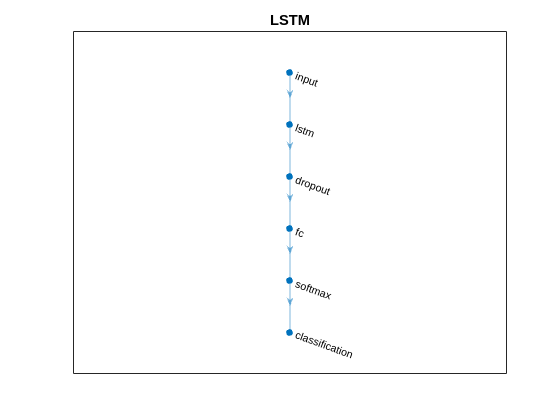

figure
plot(lgraph)
title("LSTM")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

% options = trainingOptions("adam", ...
%     MaxEpochs=500, ...
%     miniBatchSize=50, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Verbose=true);

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    miniBatchSize=50, ...
    Plots="training-progress", ...
    Verbose=true);

## Train Model

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       56.00% |       0.9076 |          0.0010 |
|       1 |          50 |       00:00:06 |       56.00% |       0.7046 |          0.0010 |
|       2 |         100 |       00:00:08 |       48.00% |       0.7387 |          0.0010 |
|       3 |         150 |       00:00:09 |       62.00% |       0.6872 |          0.0010 |
|       4 |         200 |       00:00:11 |       64.00% |       0.6618 |          0.0010 |
|       5 |         250 |       00:00:13 |       54.00% |       0.6771 |          0.0010 |
|       6 |         300 |       00:00:15 |       68.00% |       0.

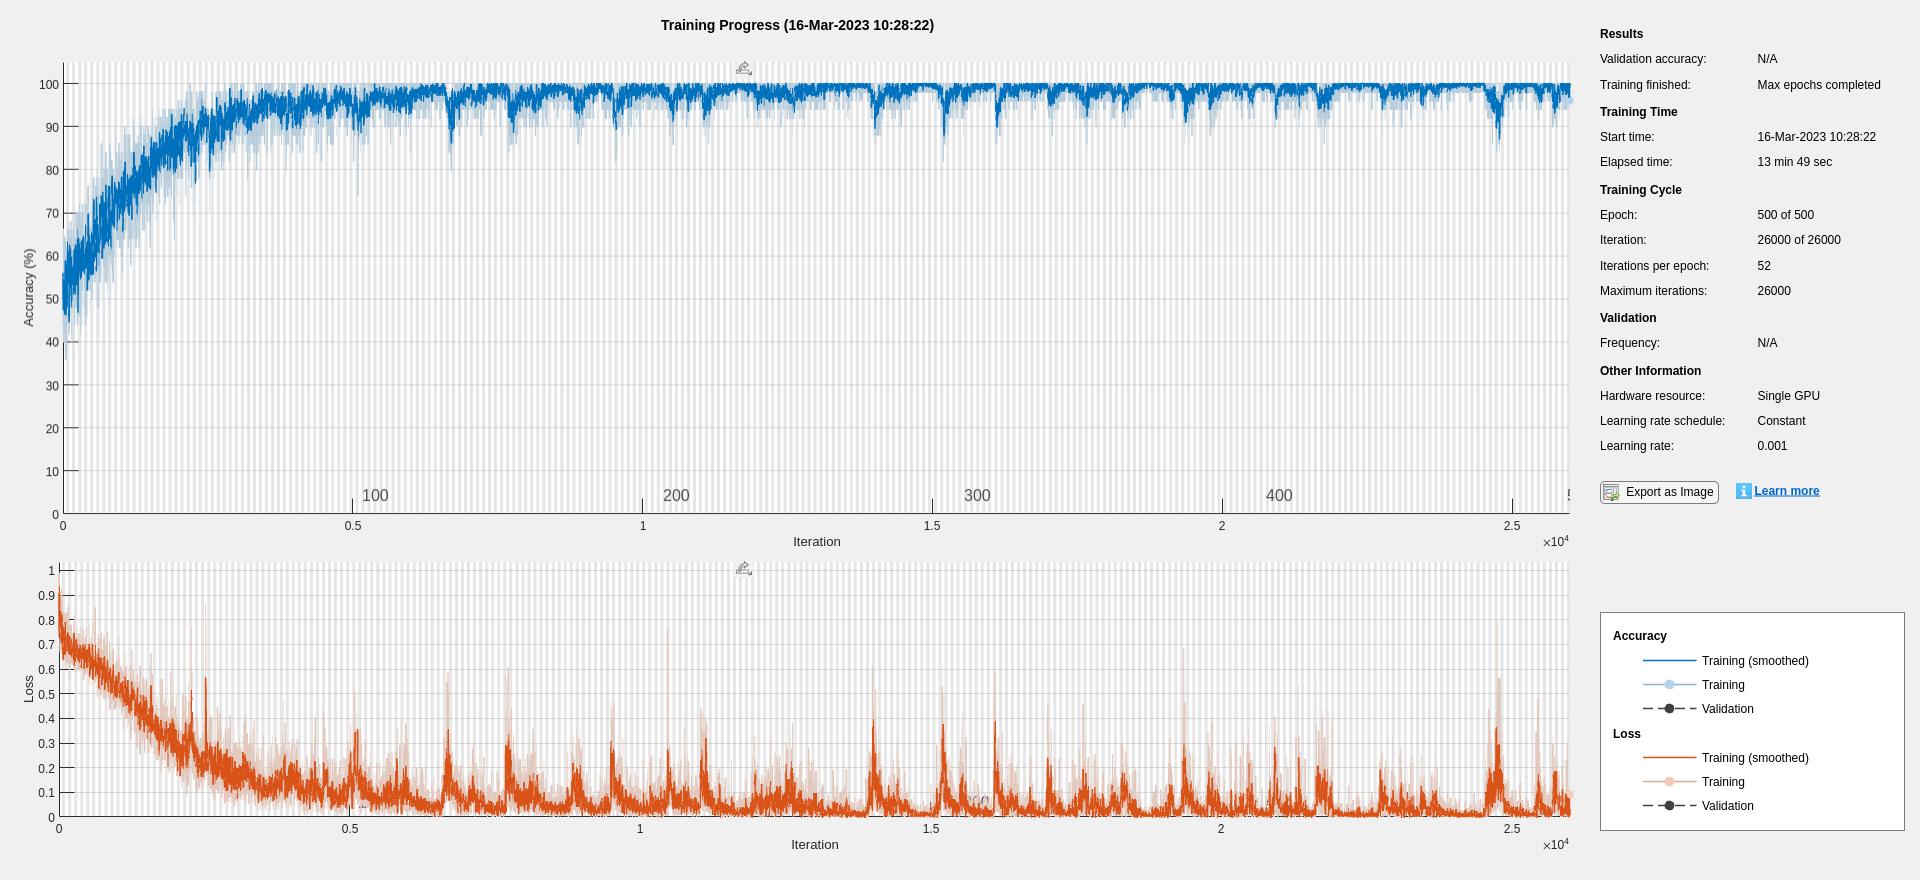

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       98.00% |       0.0879 |          0.0010 |
|       1 |          50 |       00:00:03 |      100.00% |       0.0101 |          0.0010 |
|       2 |         100 |       00:00:04 |      100.00% |       0.0060 |          0.0010 |
|       3 |         150 |       00:00:06 |       98.00% |       0.0512 |          0.0010 |
|       4 |         200 |       00:00:07 |       98.00% |       0.0598 |          0.0010 |
|       5 |         250 |       00:00:09 |      100.00% |       0.0207 |          0.0010 |
|       6 |         300 |       00:00:10 |       96.00% |       0.

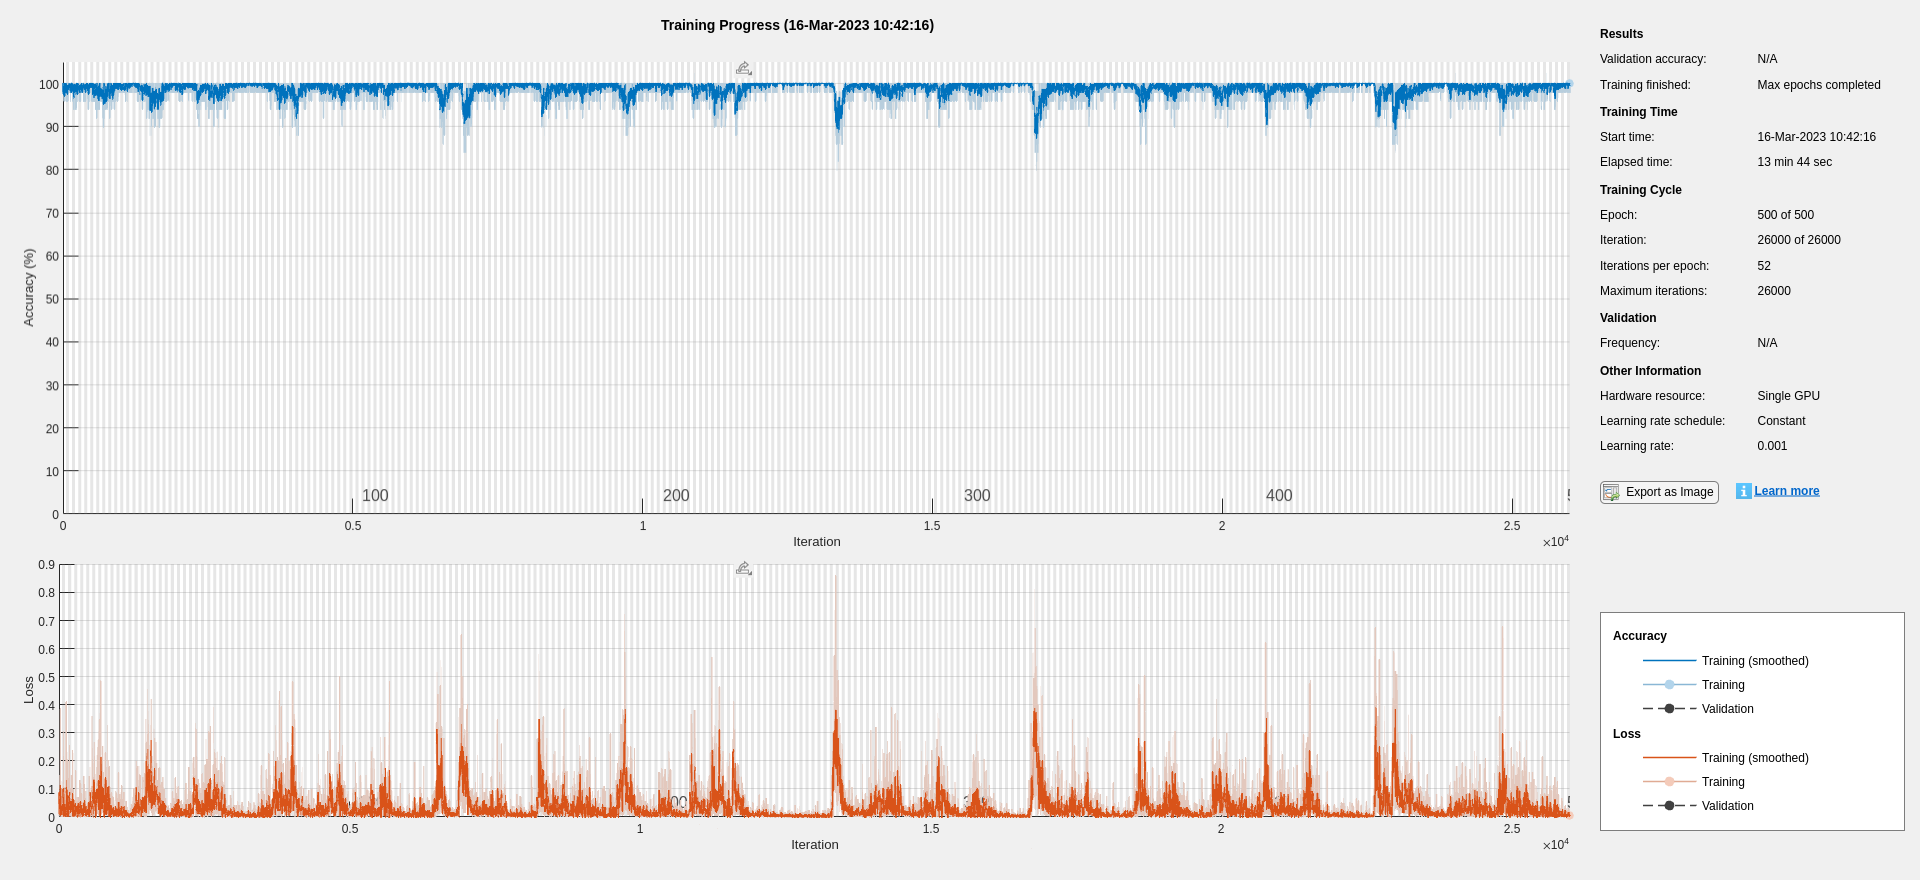

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);




% TTest --- OutTest
% YPred --- OutPred

% accuracyArray = ones(length(OutTest), 1) * -3479;
% for i = 1 : length(OutTest)
%     accuracyArray(i) = mean(OutPred{i} == OutTest{i});
% end
% accuracy = mean(accuracyArray)

Visualize the predictions for **each sample** in a confusion matrix.

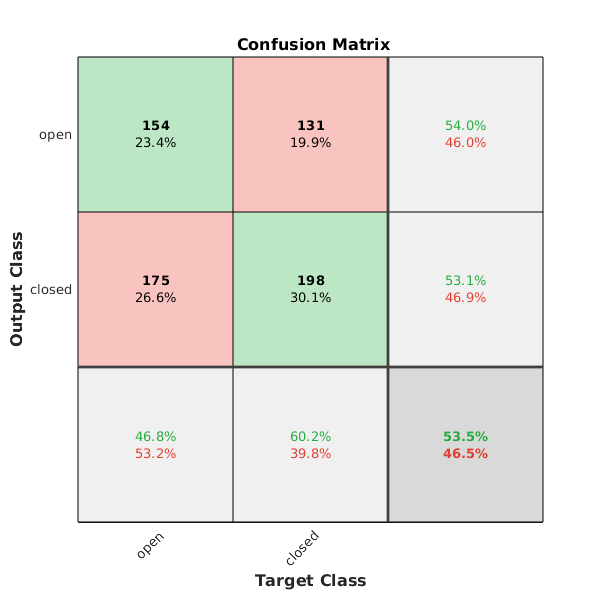

% Pred = vertcat(OutPred{:});
% True = vertcat(OutTest{:});
% plotconfusion(True(:),Pred(:));

plotconfusion(OutTest(:),OutPred(:));

Visualize the predictions for **each sample** in a confusion matrix.

% Pred = vertcat(OutPred{:});
% True = vertcat(OutTest{:});
% PredCount = countcats(Pred');
% Predictions=1*(PredCount(1,:)<PredCount(2,:));
% PredChunk = categorical(Predictions,[0 1],{'open', 'closed'});
% TrueChunk = True(:,1);
% plotconfusion(TrueChunk(:),PredChunk(:));